# Computer Assignment #7

## Ali Hamzehpour 810100129

### Part 1

In this part we want to solve the differential equation for a series RLC circuit.

#### 1-1

first we write the differential equation:


$$R\frac{di{\left(t\right)}}{dt}+\textrm{L}\;\frac{d^2 i\left(t\right)}{dt}+\frac{1}{c}\int_{-\infty }^t i{\left(\tau \right)}d\tau =v_{in} \left(t\right)$$


#### 1-2

Now we apply the Laplace Transform to the equation and find $I\left(s\right)$:


$$RsI{\left(s\right)}+Ls^2 I{\left(s\right)}+\frac{1}{c}\ I{\left(s\right)}=sV\left(s\right)$$


 
$$\Rightarrow \ I{\left(s\right)}{\left({\textrm{Ls}}^2 +Rs+\frac{1}{c}\right)}=sV\left(s\right)$$



$$\Longrightarrow I{\left(s\right)}=\frac{sV\left(s\right)}{Ls^2 +Rs+\frac{1}{c}}$$


#### 1-3

We know that $v_c {\left(t\right)}\;=\ \frac{1}{c}\int_{-\infty }^t i{\left(\tau \right)}d\tau$ so $V_c {\left(s\right)}=\frac{1}{\textrm{cs}}I\left(s\right)$. Now if we assume that $x{\left(t\right)}=V_{in} \left(t\right)$ and$y{\left(t\right)}=V_c \left(t\right)$ this can be concluded:


$$Y{\left(s\right)}=\frac{1}{c}\frac{X\left(s\right)}{Ls^2 +Rs+\frac{1}{c}}$$


#### 1-4

 If we assume that $c=\frac{4}{3},R=1\;\textrm{and}\;L=0\ldotp 25$ the block diagram will be like this:

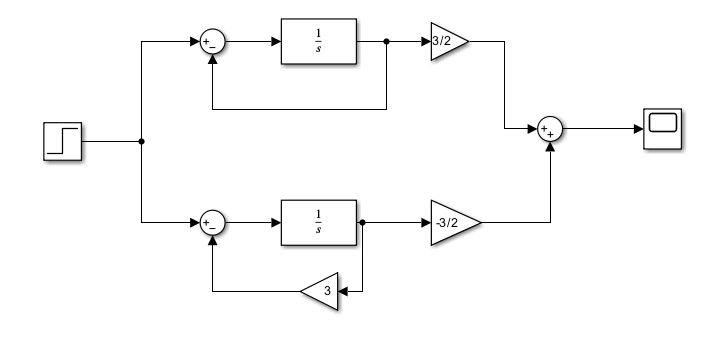

#### 1-5

Now we want to calculate the step response of the system:

we know that the impulse response is as below:


$$H{\left(s\right)}=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{3}{s^2 +4s+3}$$
 
$$=\frac{3}{\left(s+1\right)\left(s+3\right)}$$


We know that The Laplace Transform of step function is $U\left(s\right)=\frac{1}{s}$ so:


$$\Rightarrow H{\left(s\right)}U{\left(s\right)}=\frac{3}{s\left(s+1\right)\left(s+3\right)}=\ \frac{-\frac{3}{2}}{\left(s+1\right)}+\frac{\frac{1}{2}}{\left(s+3\right)}+\frac{1}{s}$$


Now if we calculate the inverse Laplace Transform of it we'll have the step response of the system:


$$S{\left(t\right)}\;=\ -\frac{3}{2}e^{-t} u{\left(t\right)}+\frac{1}{2}e^{-3t} u{\left(t\right)}+u\left(t\right)$$


If we plot this function in MATLAB:

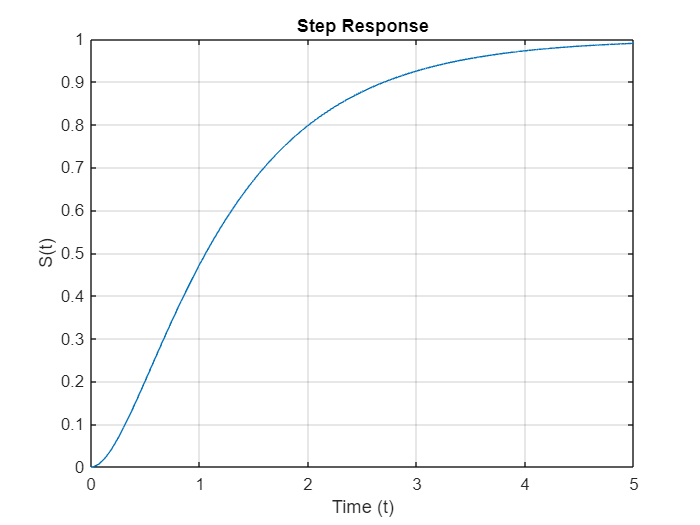

t = 0 : 1/1000 : 5; 
u = heaviside(t);  

y = -3/2 * exp(-t) .* u + 1/2 * exp(-3*t) .* u + u;

plot(t, y);
title('Step Response');
xlabel('Time (t)');
ylabel('S(t)');
grid on;

#### 1-6

Now we test this system with step input in Simulink:

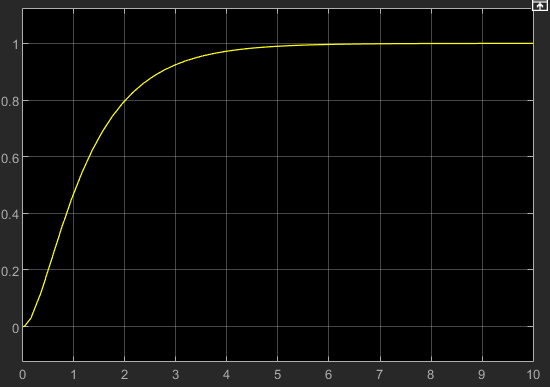

As you see the result is the same function that we calculated in the previous part.

### Part 2

In a car, the body is connected to its wheels via suspension system. When the car hits a bump, this system tries to cancel the sudden movement of the wheels so the car body doesn't move that much. it uses a spring and a damper which both compresses when the car hits a bump. damper creates a force to keep the height of the car body and the damper makes a fraction force.

Now we want to model this in a mathematical equation:

- M is the mass of the car.

- $x\left(t\right)$ is the vertical displacement of the wheels.

- $y\left(t\right)$ is the vertical displacement of the M which basically shows the movements of the car body after it hits a bump.

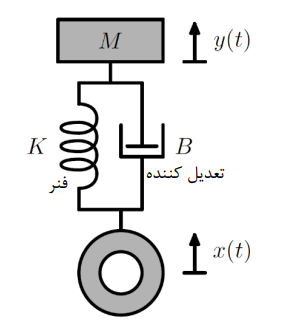

Using dynamics we can write this equation between our variables:


$$K{\left(x{\left(t\right)}-\ y{\left(t\right)}\right)}+\ B{\left(\frac{dx{\left(t\right)}}{dt}\ -\frac{dy{\left(t\right)}}{dt}\right)}=\ M\frac{d^2 y{\left(t\right)}}{dt^2 }$$


### 2-1

    First we assume that $M=1$ and $K=1$and then rewrite the equation in a second-order ODE format:


$$\frac{d^2 y{\left(t\right)}}{dt^2 }+\ B\frac{dy{\left(t\right)}}{dt}+\ y{\left(t\right)}=\ x{\left(t\right)}+\ B\frac{dx{\left(t\right)}}{dt}$$


#### 2-2

    Then we apply Lapalce Transform to the equation and find the function that converts $Y\left(s\right)$ to $X\left(s\right):$


$$s^2 Y{\left(s\right)}+BsY{\left(s\right)}+Y{\left(s\right)}=X{\left(s\right)}+BsX{\left(s\right)}$$
   


$$\Rightarrow \ Y{\left(s\right)}{\left(s^2 +\ Bs\ +\ 1\right)}=\ X{\left(s\right)}{\left(1+Bs\right)}$$



$$\Rightarrow \ H{\left(s\right)}\;=\;\frac{1+Bs}{s^2 +Bs+1}$$


In order to easily draw the block diagram of the equation, we rewrite the equation as below:


$$Y{\left(s\right)}+\frac{BY{\left(s\right)}}{s}+\frac{Y{\left(s\right)}}{s^2 }=\frac{X{\left(s\right)}}{s^2 }+\frac{BX{\left(s\right)}}{s}$$



$$\Rightarrow Y{\left(s\right)}\;=\frac{1}{s^2 }{\left(X{\left(s\right)}-Y{\left(s\right)}\right)}+\frac{1}{s}{\left(BX{\left(s\right)}-BY{\left(s\right)}\right)}$$


Now we draw the block diagram in Simulink:

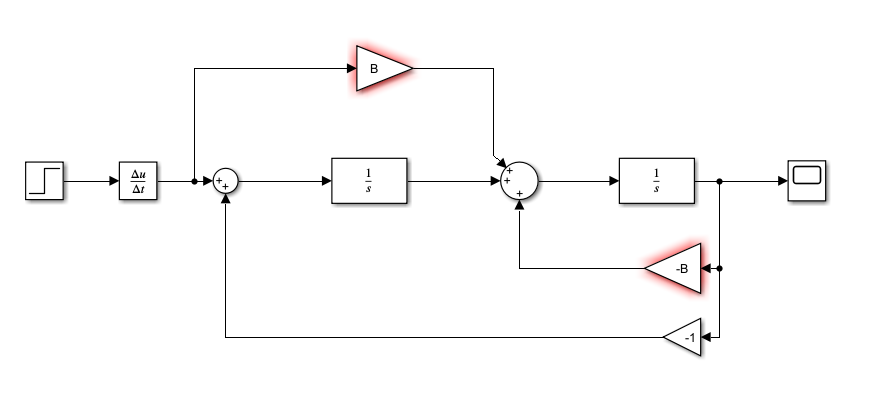

###  2-3

    In this section we assume that $B=0$ which means the damper don't generate any force. In this situation we can write the impulse respnose as below:


$$H{\left(s\right)}\;=\frac{1}{s^2 +1}\ \longrightarrow h{\left(t\right)}=\mathrm{s}\mathrm{i}\mathrm{n}\left(t\right)u\left(t\right)$$


We can test it in simulink and as we see the result is a sinus function:

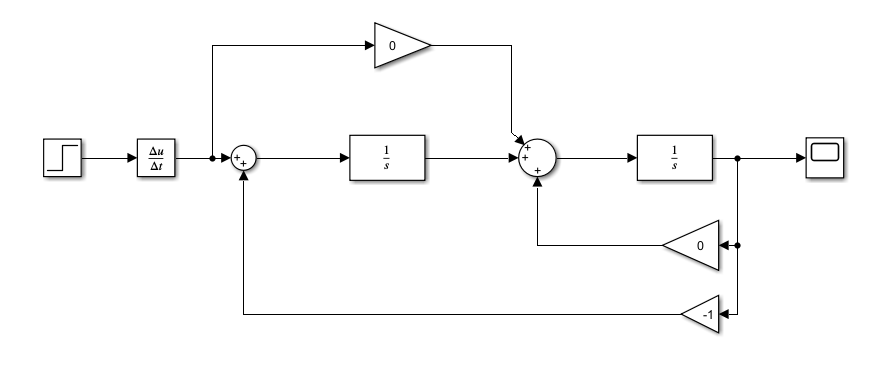

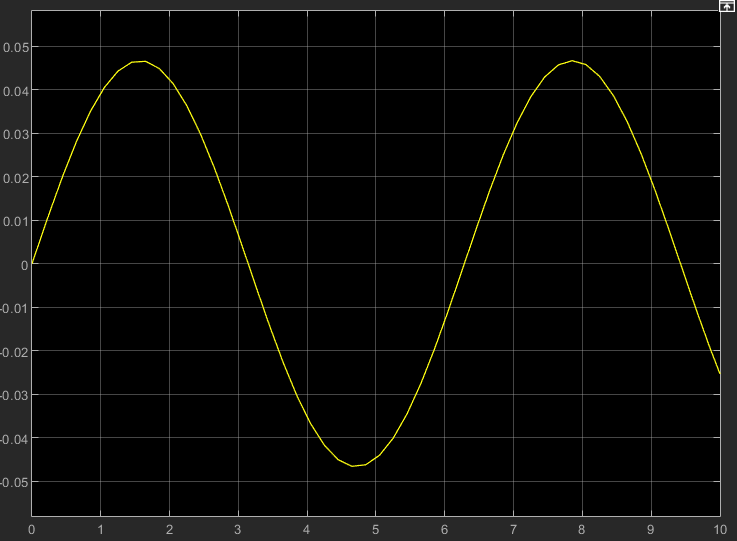

This means that if we don't have damper in suspension system, the car body will go up and down repeatedly after it hits a bump!

### 2-4

    The poles of $H\left(s\right)$ are the answers of $s^2 +Bs+1=0$ so if we want the poles to be Real, the answers to that equation should be Real:


$$∆=B^2 -4\ge 0\ \Rightarrow \;{\left∣B\right∣}\;\ge \;2\$$


So the least positive value for B is 2.

In this situation we find the impulse response of the equation as below:


$$H{\left(s\right)}=\frac{1+2s}{s^2 +2s+1}\ \longrightarrow h{\left(t\right)}\;=\mathrm{\ }-{\mathrm{e}}^{-\mathrm{t}} \left(t-2\right)u\left(t\right)$$


We test this situation in Simulink:

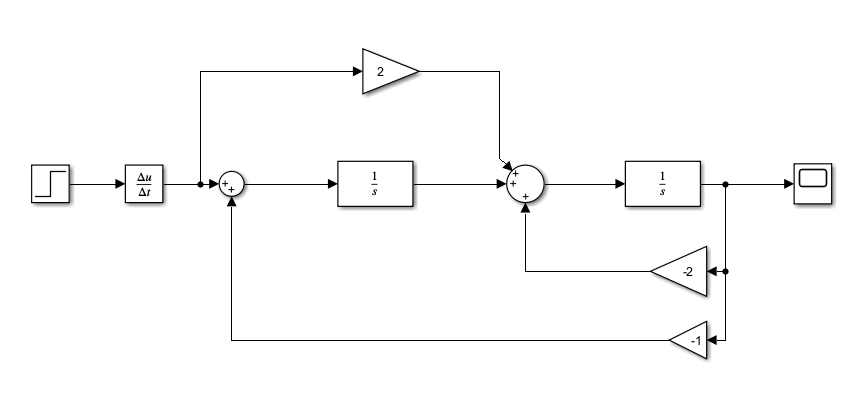

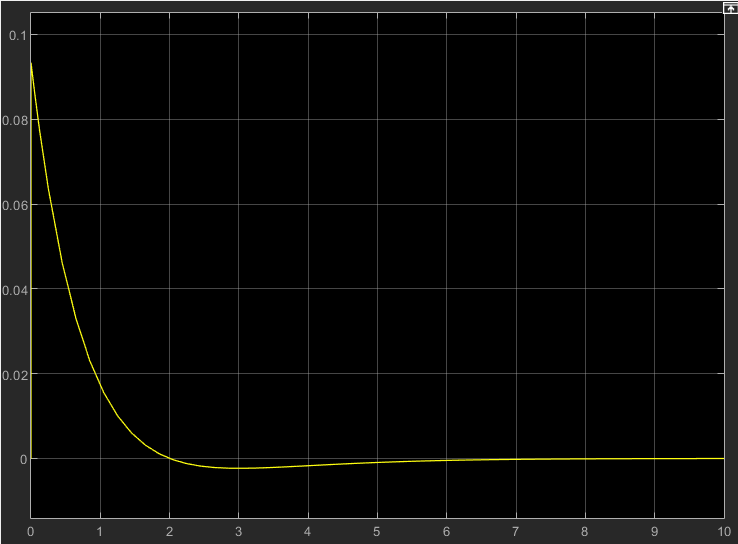

In this situation, suddenly the car body goes up but then goes down in a smooth way and then it becomes stable and we don't have that sinus shape that we had in the previous part.

#### 2-5

Now we assume that $B=100$. In this situation the impulse respnse will be as below:


$$H{\left(s\right)}=\frac{1+100s}{s^2 +100s+1}\ \approx \;\frac{1+100s}{{\left(s+100\right)}{\left(s+0.01\right)}}\ \longrightarrow h{\left(t\right)}\;=\mathrm{\ }100\;{\mathrm{e}}^{-100\mathrm{t}} u\left(t\right)$$


Now we test it in Simulink:

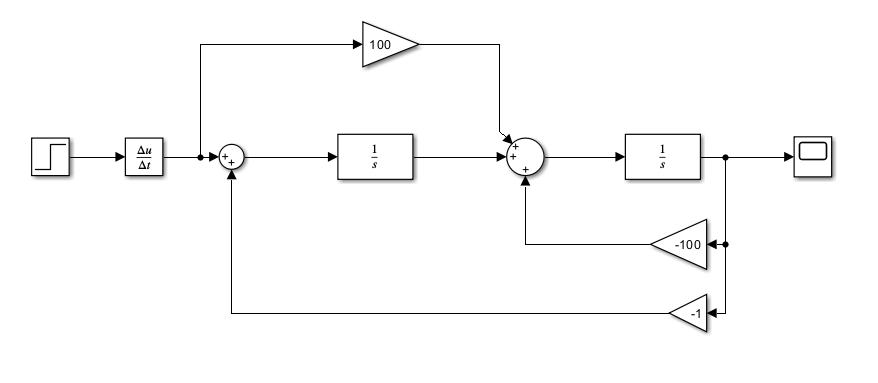

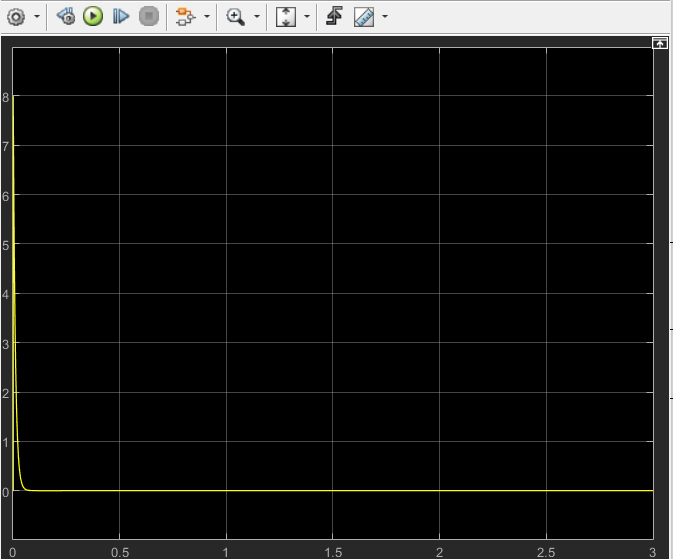

In this situation, it damps out oscillations more quickly but it's more suddent than B = 2.

Also the shape of the simulation result is similar to what we calculated in theory.

#### 2-6

***which value for B was better? ****B = 2*

- B = 0: It was completely bad because we had no damping and after the car hits the bump, the car body will oscillate.

- B = 2: This case was ideal it damps out oscillations in a smooth way.

- B = 100: In this situation it damps out oscillations in a smooth way quicklier but the problem is its so sudden and when it hits the bump, the car body movement is so much higher than B = 2.

### Part 3

If we don't have initial rest condition in our differential equation we can't use Laplace Transform to solve the equation instead we use Unilateral Laplace Transform

The equation is:


$$d^2 \frac{y\left(t\right)}{{\textrm{dt}}^2 }+3\;\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}+2y\left(t\right)=x\left(t\right)$$


The initial conditions are:


$$y\left(0^- \right)=1,y^{\prime } \left(0^- \right)$$


and $x\left(t\right)=5\;u\left(t\right)$.

#### 3-1

First we solve this equation using Unilateral Laplace Transform:


$$s{\left(sy{\left(s\right)}+y{\left(0^- \right)}\right)}-y^{\prime } {\left(0^- \right)}+3sy{\left(s\right)}-3y^{\prime } {\left(0^- \right)}+2y{\left(s\right)}=X\left(s\right)$$



$${\Rightarrow s}^2 y{\left(s\right)}-s-1+3sy{\left(s\right)}-3+2y{\left(s\right)}=X{\left(s\right)}$$



$${\Longrightarrow s}^2 y{\left(s\right)}+{\left(2+3s\right)}y{\left(s\right)}=X{\left(s\right)}+s+4$$


since $X\left(s\right)=\frac{5}{s}$ then:


$${\left(s^2 +3s+2\right)}Y{\left(s\right)}=\frac{5}{s}+s+4$$



$$\Rightarrow Y{\left(s\right)}=\ \frac{\frac{5}{s}+s+4}{s^2 +3s+2}=\frac{s^2 +4s+5}{s\left(s+1\right)\left(s+2\right)}$$


then if we apply inverse Laplace Transform we can find y(t):


$$y{\left(t\right)}=\frac{e^{-2t} }{2}-2\ e^{-t} +\frac{5}{2}$$


#### 3-2

In this section we solve the same equation using MATLAB functions:

syms y(t)
sys = tf(1, 1);
Dy = diff(y);

ode = diff(y,t,2) + 3 * diff(y, t, 1) + 2*y == 5 * step(sys);
cond1 = y(0) == 1;

$$ySol(t) = \frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{5}{2}$$

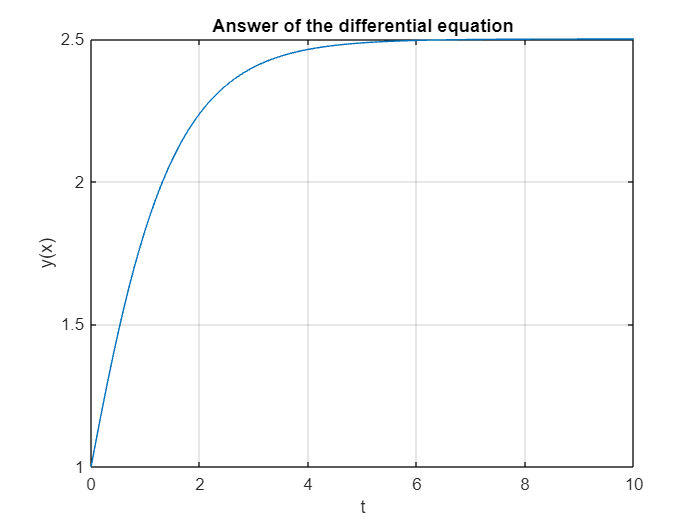

cond2 = Dy(0) == 1;
conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds);
ySol = simplify(ySol)

figure;
ts = 0 : 0.1 : 10;
plot(ts, ySol(ts)); 

title('Answer of the differential equation');
xlabel('t');
ylabel('y(x)');
grid on;

 As you can see the answer is the same function that we calculated in the previous part.